# **1D concentration profile from a reconstructed APT tip**

**Voxelisation of atom probe data in 1D, calculating concentrations, creating 1D concentration profiles**

In order to calculate a 1D concentration profile, the APT tip needs to be already reconstructed, and therefore the mass spectrum has to be ranged and the pos file parsed (so that a ion variable (column name) is generated). These steps can be found in the live script ***FirstSteps***.

## Creation of grid vectors

The function *binVectorsFromDistance* creates a set of grid vectors to be used in nD binning (here for one dimension). First, the distance variable needs to be specified, in which the binning will be performed. If no particular ROI is wanted, the typical distance is represented by the z axis of the pos variable.

dist = pos.z; % determine the distance variable to be binned

There are **two modes** possible. The user has to choose the wanted case and comment the unwanted case in this live script (either by pushing the button in the task bar or pressing the keys *Ctrl + R*) in order to execute the live script properly since the input variables *bin* and *mode* are practically 'connected' (for the mode *'distance'*  values between 1 and around 20 make sense, whereas the mode *'count'* needs much higher values).

**Case #1:** *'distance'* is used as *mode*, which resembles the distance in nm from bin edge to bin edge

bin = 1; % bin width in nm
mode = 'distance';
[binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

**Case #2:** *'count'* is used as *mode*, which resembles the number of counts, which are present between two consecutive bin edges

% bin = 390000; % number of counts within each bin
% mode = 'count';
% [binCenters, binEdges] = binVectorsFromDistance(dist,bin,mode); % creates bin centers and bin edges of the voxels
 

## Voxelisation of the data set

In the next step, the voxelisation will be performed based on the bin edges. This means in 1D, that the reconstructed APT tip is separated into slices of the size determined in the previous step. 

Each slice exhibits either a specified thickness in nm (for mode *'distance'*) or consists of a certain number of counts (for mode *'count'*). As a side note, be aware that the final slice most likely is thinner or contains less atoms compared to the other slices. This is only logical and relates to the way the slices are created.

vox = posNdBin(pos, dist, binEdges); % creates a cell array of various pos subsets, representing the voxelisation of the pos variable
 

## Creation of an anonymous function

In the next step, a so-called 'anonymous function' will be defined. This means that a function handle will be created, here it is called *concentrationKernel*. By doing so, the subsequent step can be executed more easily.

As input, the detector efficiency is needed. For example, in case of the LEAP 4000X HR, this value is 0.37 or 37 %, respectively.

The inputs *excludeListConc* and *volumeName* are optional:

detEff = 37; % detector efficiency, input as decimal or percentage figure possible
excludeListConc = {'unranged'}; % list of ions that shall not be considered for the concentration calculation, unranged atoms appear as 'unranged', optional
volumeName = '6371'; % name of the volumes, parsed as character array, optional
concentrationKernel = @(pos) posCalculateConcentrationSimple(pos, detEff, excludeListConc, volumeName);
 

## Plotting of a 1D concentration profile

In order to plot a 1D concentration profile, it is necessary to execute following function so that the calculated concentration values correspond to a distance value.

conc1D = binApplyConcentrationKernel(vox, binCenters, concentrationKernel, {'nm'});

To plot the concentration over the distance, the function *concentrationProfilePlot* is needed. The user can specify an exclude list (now *excludeListPlot*) to exclude certain species from plotting.

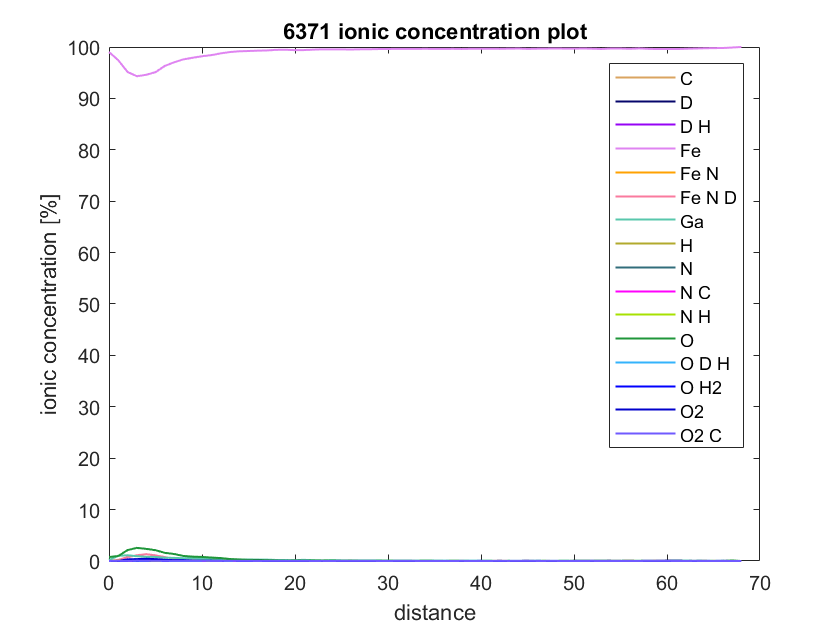

excludeListPlot = {'unranged'};  % list of ions that shall not be displayed in the plot, optional
[p, ax, f] = concentrationProfilePlot(conc1D([conc1D.format=='concentration'], :),excludeListPlot,colorScheme); % plots the wanted species over the distance

## Calculation of concentrations for each voxel

With the next function, the user can extract the concentration values of all ranged ions, except the elements of the *excludeList*, for each voxel.

conc = cellfun(concentrationKernel, vox, 'UniformOutput', false); % performs the function 'ck' on each element of the cell array 'vox'
 

## Extraction of concentration values for a specific species

In order to access the concentration values for a specific species, following function can be used. Just enter the wanted element or complex ion name. The output is a column vector with values representing the concentration (as a fraction) of the wanted species for each voxel.

concWantedSpecies = cellfun(@(x) x.H(x.format == 'concentration'), conc); % enter element symbol (e.g. Fe) or complex ion (e.g. ("O H2")
 